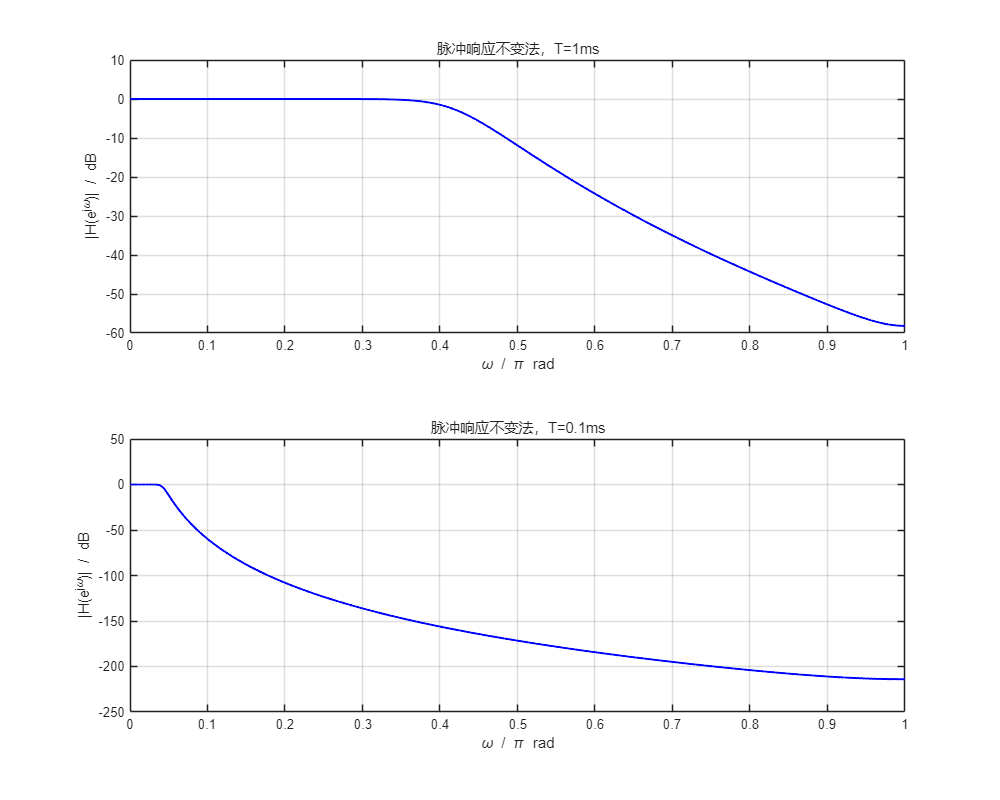

%% 巴特沃兹IIR数字低通滤波器设计-脉冲响应不变法和双线性变换法
% 要求f_p=200Hz，δ_p≤3dB，f_s=350Hz，δ_s≥35dB
% 绘制T1=1ms、T2=0.1ms时的数字滤波器幅频特性曲线

fp = 200;      % 通带截止频率(Hz)
fs = 350;      % 阻带起始频率(Hz)
dp = 3;        % 通带衰减最大值(dB)
ds = 35;       % 阻带衰减最小值(dB)

T1 = 1/1000;   % 采样周期1ms
fT1 = 1/T1;    % 采样频率1000Hz
T2 = 1/10000;  % 采样周期0.1ms  
fT2 = 1/T2;    % 采样频率10000Hz

% 模拟角频率
wp_analog = 2*pi*fp;  % 模拟通带截止角频率
ws_analog = 2*pi*fs;  % 模拟阻带起始角频率

% 设计模拟巴特沃兹低通滤波器
[N, wn_analog] = buttord(wp_analog, ws_analog, dp, ds, 's');
[num_analog, den_analog] = butter(N, wn_analog, 's');

w = linspace(0, pi, 1000);

%% 图形1: 脉冲响应不变法 - T=1ms和T=0.1ms对比
figure('Position', [100, 100, 1000, 800]);

% 脉冲响应不变法 - T=1ms
[numd1_1, dend1_1] = impinvar(num_analog, den_analog, fT1);
H1_1 = freqz(numd1_1, dend1_1, w);
H1_1_dB = 20*log10(abs(H1_1));

subplot(2,1,1);
plot(w/pi, H1_1_dB, 'b-', 'LineWidth', 1.5);
grid on;
title('脉冲响应不变法，T=1ms');
xlabel('\omega / \pi rad');
ylabel('|H(e^{j\omega})| / dB');
% axis([0, 1, -60, 5]);

% 脉冲响应不变法 - T=0.1ms
[numd1_01, dend1_01] = impinvar(num_analog, den_analog, fT2);
H1_01 = freqz(numd1_01, dend1_01, w);
H1_01_dB = 20*log10(abs(H1_01));

subplot(2,1,2);
plot(w/pi, H1_01_dB, 'b-', 'LineWidth', 1.5);
grid on;
title('脉冲响应不变法，T=0.1ms');
xlabel('\omega / \pi rad');
ylabel('|H(e^{j\omega})| / dB');

%% 图形2: 双线性变换法 - T=1ms和T=0.1ms对比
figure('Position', [200, 100, 1000, 800]);

% 直接对模拟频率进行预畸变
wp_prewarped = (2/T1) * tan(pi*fp*T1);  % 注意：使用fp而不是数字频率
ws_prewarped = (2/T1) * tan(pi*fs*T1);

% 使用预畸变后的频率重新设计模拟滤波器
[N_pre, wn_pre] = buttord(wp_prewarped, ws_prewarped, dp, ds, 's');
[num_pre, den_pre] = butter(N_pre, wn_pre, 's');

% 双线性变换
[numd_pre, dend_pre] = bilinear(num_pre, den_pre, fT1);

[H_pre, w_pre] = freqz(numd_pre, dend_pre, 1024);
H_pre_dB = 20*log10(abs(H_pre));

subplot(2,1,1);
plot(w_pre/pi, H_pre_dB, 'b-', 'LineWidth', 1.5);
grid on;
title('双线性变换法，T=1ms');
xlabel('\omega / \pi rad');
ylabel('|H(e^{j\omega})| / dB');
% axis([0, 1, -60, 5]);

% T=0.1ms
wp_prewarped_01 = (2/T2) * tan(pi*fp*T2);
ws_prewarped_01 = (2/T2) * tan(pi*fs*T2);
[N2, wc2] = buttord(wp_prewarped_01, ws_prewarped_01, dp, ds, 's');
[num2, den2] = butter(N2, wc2, 's');
[numd2, dend2] = bilinear(num2, den2, fT2);

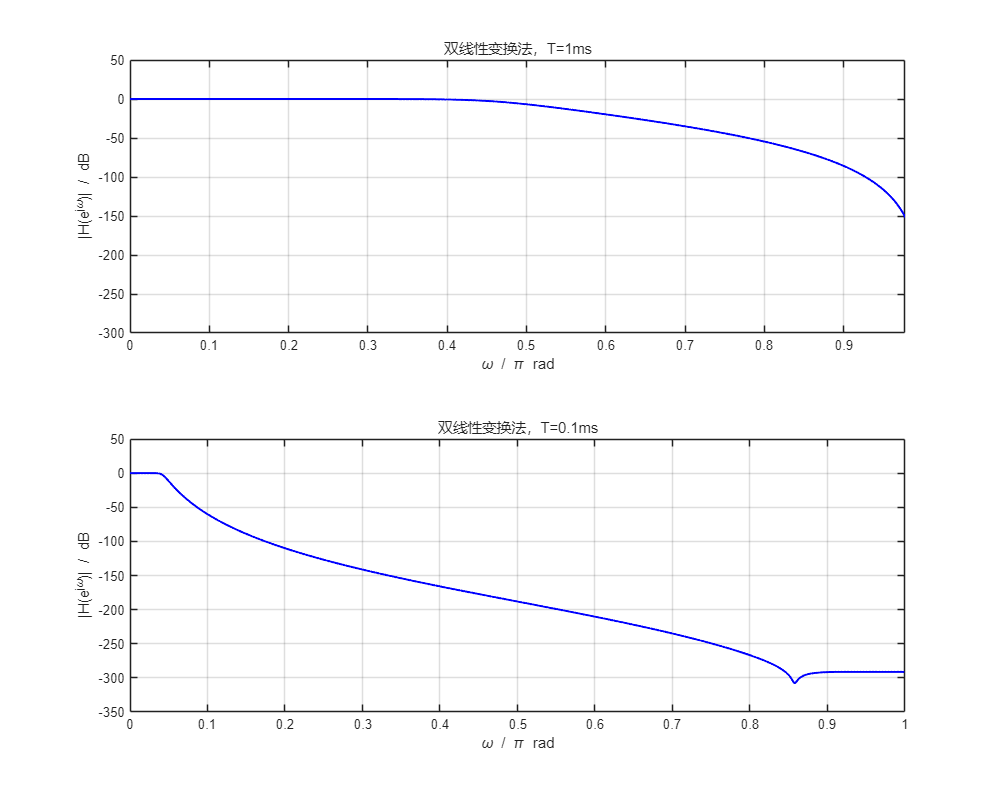

[H2, w2] = freqz(numd2, dend2, 1024);
H2_dB = 20*log10(abs(H2));

subplot(2,1,2);
plot(w2/pi, H2_dB, 'b-', 'LineWidth', 1.5);
grid on;
title('双线性变换法，T=0.1ms');
xlabel('\omega / \pi rad');
ylabel('|H(e^{j\omega})| / dB');